train= readtable('Icecream.csv');

%initializing variables

X= train.Temperature__C_;
Y= train.IceCreamSales_units_;


%polynomial regression function

N= size(Y,1);

X_N=[X,X.^2,X.^3,X.^4,X.^5]; %Polynomial function

X=normalize(X_N);

X=[ones(N,1),X];

%initializing theta
theta= ones(6,1);

iterations = 50000;

%learning rate
alpha=0.1;

%cost per iteration

cost= zeros(iterations,1);

for i=1:iterations
    %erroe function
    h= X*theta-Y;
    %updating theta 
    for j=1:size(theta,1)
        theta(j)=theta(j)-(alpha/N)*h'*X(:,j);
    end
    
    %cost calculating
    cost(i)=(1/(2*N))*sum(h.^2);
end

fprintf('theta0 = %f \ntheta1 = %f \ntheta2= %f \ntheta3 = %f', theta(1),theta(2),theta(3),theta(4));

theta0 = 15.905308 
theta1 = -6.007543 
theta2= 14.161931 
theta3 = 6.830646

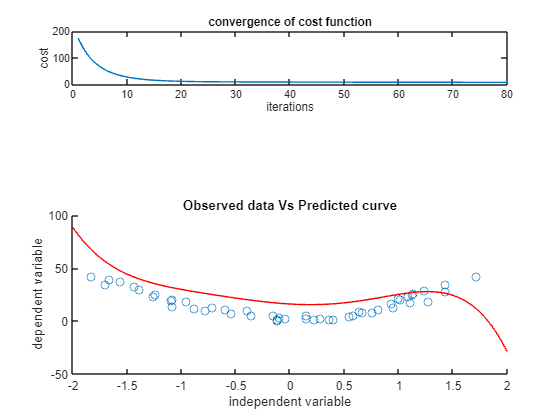


%ploting  the data
figure;
subplot(4,1,1)
plot(cost(1:0));
xlabel("iterations");
ylabel('cost');
title('convergence of cost function');

set=[-2,2];
subplot(4,1,[3,4]);
b=X(:,2);
scatter(b,Y);
hold on;
l=theta(1)+theta(2)*linspace(set(1),set(2),1000)+theta(3)*(linspace(set(1),set(2),1000).^2)+theta(4)*(linspace(set(1),set(2),1000).^3)+ theta(5)*(linspace(set(1),set(2),1000).^4)+ theta(6)*(linspace(set(1),set(2),1000).^5);
n=linspace(set(1),set(2),1000);
plot(n,l,'r');
xlabel("independent variable");
ylabel("dependent variable");
title("Observed data Vs Predicted curve");


%regularisation of the above curve

lambda=50;

N=size(Y,1);

for i=1:iterations
    % error fucntion
    h=X*theta-Y;
    for j=1:size(theta,1)
        theta(j)=(1-(alpha*lambda)/N)*theta(j)-(alpha/N)*h'*X(:,j);
    end
    cost(i)=(1/(2*N))*sum(h.^2)+ (lambda/(2*N))*sum(theta.^2);
end

fprintf('theta0 = %f \ntheta1 = %f \ntheta2= %f \ntheta3 = %f', theta(1),theta(2),theta(3),theta(4));

theta0 = 7.872324 
theta1 = -0.845713 
theta2= 4.175717 
theta3 = -0.323505

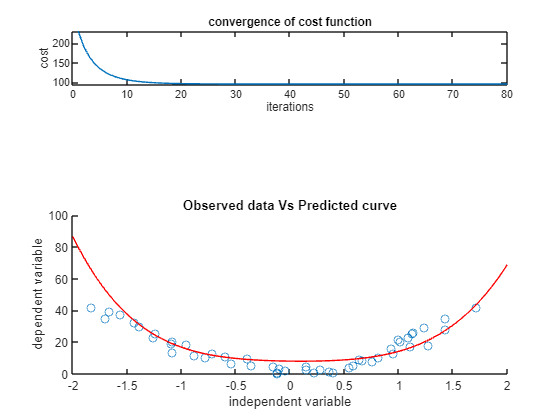


%ploting  the data
figure;
subplot(4,1,1)
plot(cost(1:80));
xlabel("iterations");
ylabel('cost');
title('convergence of cost function');

set=[-2,2];
subplot(4,1,[3,4]);
b=X(:,2);
scatter(b,Y);
hold on;
l=theta(1)+theta(2)*linspace(set(1),set(2),1000)+theta(3)*(linspace(set(1),set(2),1000).^2)+theta(4)*(linspace(set(1),set(2),1000).^3)+ theta(5)*(linspace(set(1),set(2),1000).^4)+ theta(6)*(linspace(set(1),set(2),1000).^5);
n=linspace(set(1),set(2),1000);
plot(n,l,'r');
xlabel("independent variable");
ylabel("dependent variable");
title("Observed data Vs Predicted curve");